# 034IN - Fundamentals of Automatic Control - A.Y. 2024/2025

# First Partial Examination - 2025/04/11

# Exercise 2A: From an ODE Set to State Equations, then to a Transfer Function, and back to a State-Space Representation

**Tag List**: `[STANDARD ASSESSMENT] [PARTIAL CREDIT] [SYMBOLIC] `

## Introduction

A **balance** **system** is a mechanical system in which the center of mass is balanced above a pivot point. Some common examples of balance systems are shown in Figure

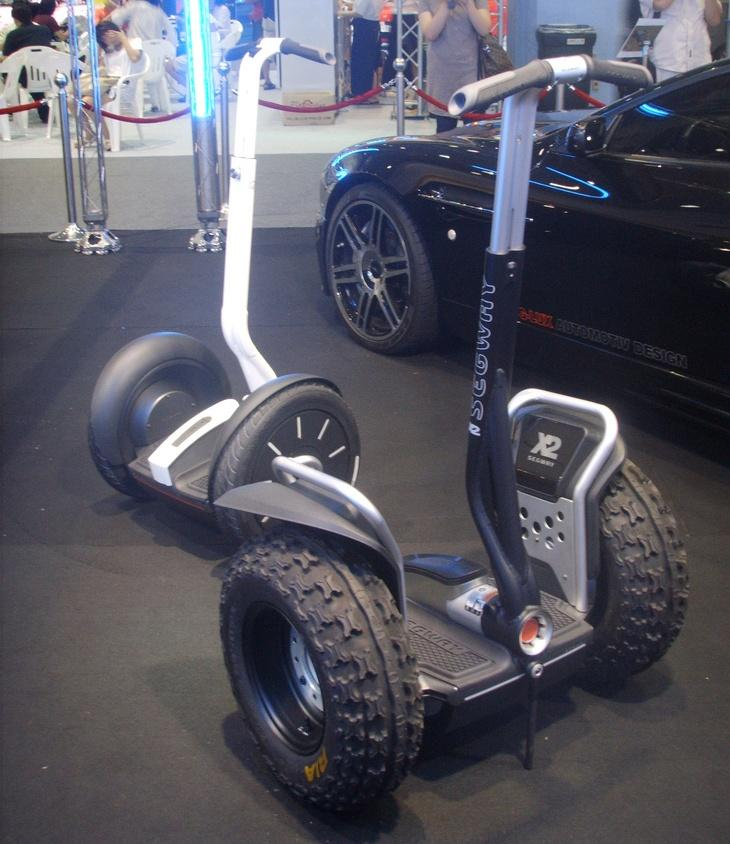  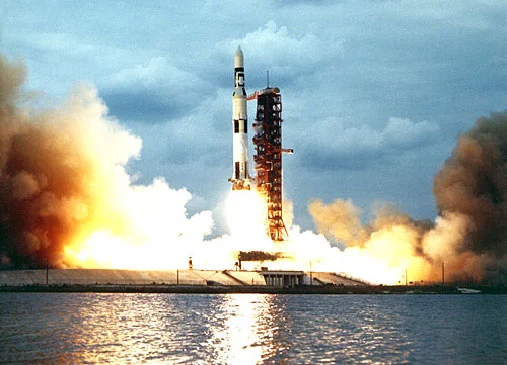  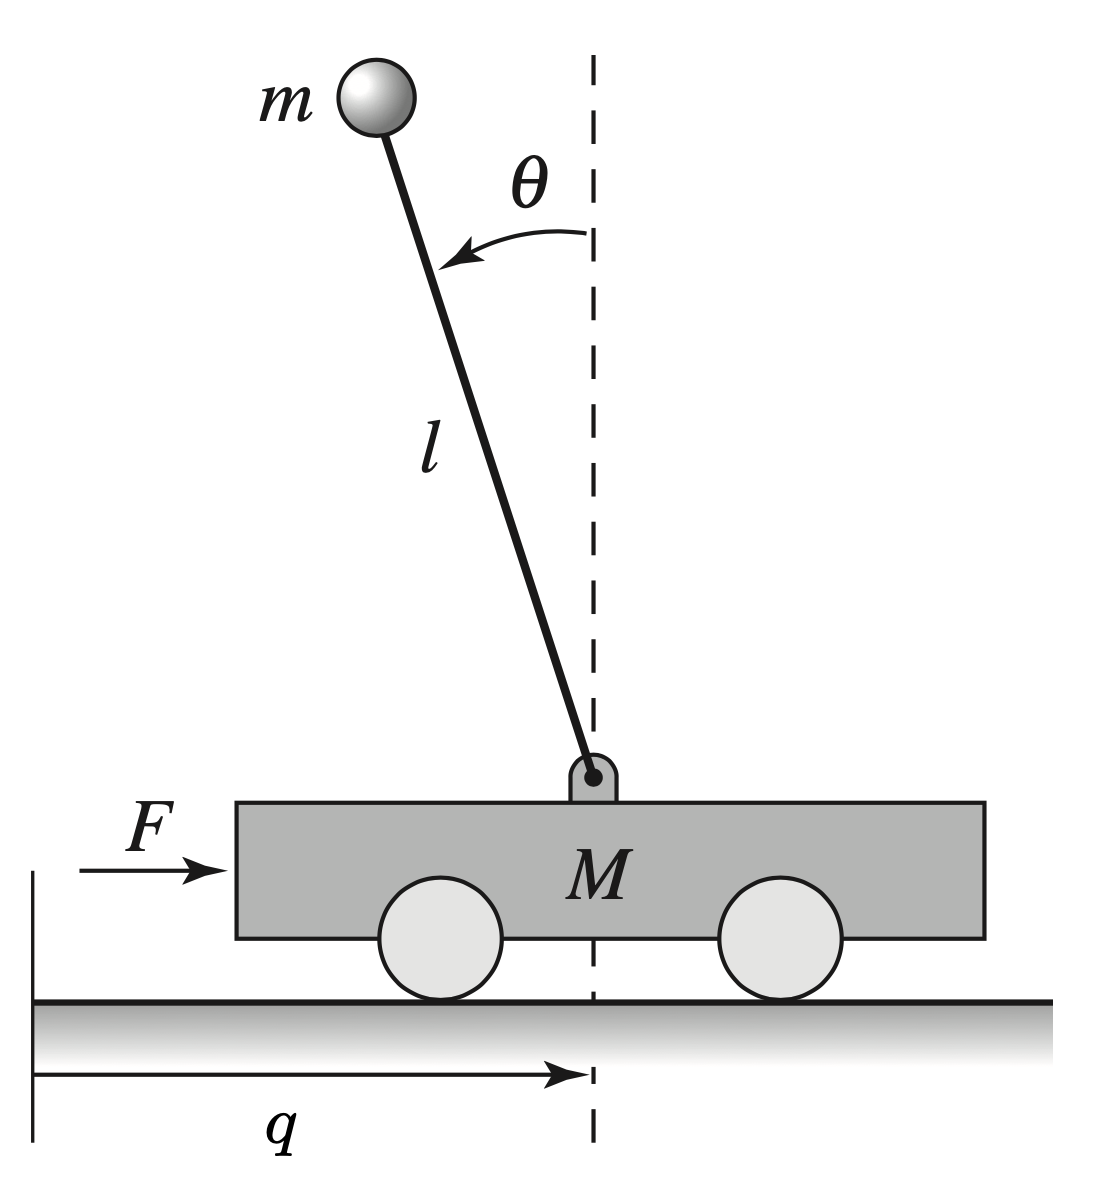

Figure (a): source [1]                                   Figure (b): source [2]                                          Figure (c)

The Segway® Personal Transporter (Figure (a) ) uses a motorized platform to stabilize a person standing on top of it. When the rider leans forward, the transportation device propels itself along the ground but maintains its upright position. Another example is a rocket (Figure (b)), in which a gimballed nozzle at the bottom of the rocket is used to stabilize the body of the rocket above it. Other examples of balance systems include humans or other animals standing upright or a person balancing a stick on their hand.

Figure (c) shows a simplified diagram for a balance system consisting of an **inverted pendulum on a cart**. 

To model this system, we adopted the following notation:

- the variables $q$ and $\dot{q}$ represent the position and the translational speed of the base of the system;

- the variables $\theta$ and $\dot{\theta}$ represent the angle and angular rate of the structure above the base;

- $F$ is the force applied at the base of the system and it is the unique input for the system: $u(t) = F(t)$;

- the angle $\theta$ represent the output of the system: $y(t) = \theta(t)$.

Moreover, we assume that

- the angle $\theta$ is very close to $0$;

- the angular rate $\dot{\theta}$ is small.

With these sets of definitions and assumptions , the dynamics of the system can be computed using Newtonian mechanics and have the form of the following set of** two second-order linear ODEs** 


$$\left\{\begin{array}{rcl}
\ddot{q}(t) &=& \frac{m^2\,l^2\,g}{\mu}\, \theta(t) -\frac{c\,J_t}{\mu}\, \dot{q}(t) - \frac{\gamma\,l\,m}{\mu}\, \dot{\theta}(t) + \frac{J_t}{\mu}\,u(t)\\ \\
\ddot{\theta}(t) &=& \frac{M_t\,m\,g\,l}{\mu}\, \theta(t) -\frac{c\,l\,m}{\mu} \dot{q}(t) - \frac{\gamma\,M_t}{\mu} \dot{\theta} + \frac{l\,m}{\mu}\,u(t) \\ \\
y(t) &=& \theta(t)

\end{array}\right. \qquad \quad(*)$$


where

- $M$ is the mass of the base;

- $m$ and $J$ are the mass and moment of inertia of the system to be balanced;

- $l$ is the distance from the base to the center of mass of the balanced body;

- $c$ and $\gamma$ are coefficients of viscous friction;

- $g$ is the acceleration of gravity;

- the total mass is defined as: $M_t = M+m$ ;

- the total inertia is: $J_t = J+m\,l^2$

- to simplify the notation into the ODE set, we defined: $\mu = M_t\,J_t-m^2\,l^2$

You are asked to 

- determine a **state-space representation** $\mathcal{S}$ of the balance system described by the ODEs $(*)$, assuming the following state variables


$$\left\{\begin{array}{rcl}
x_1(t) &:=& \theta(t) \\
x_2(t) &:=& \dot{\theta}(t) = \dot{x}_1(t) \\
x_3(t) &:=& q(t) \\
x_4(t) &:=& \dot{q}(t) = \dot{x}_3(t)
\end{array} \right. \qquad (+)$$


- given the state-space representation $\mathcal{S}$, compute the corresponding **transfer** **function** $T_{u\,y}(s)$ from the input $u(t)$ to the output $y(t)$.

## Assignment

**Note**: the parameters $M$, $m$, $J$, $l$, $c$, $\gamma$, $g$, $M_t$, $J_t$, and $\mu$ have been predefined and they are available as the numeric variables  `M`, `m`, `J`, `l`, `damp_c`, `damp_gamma`, `g`, `M_t`, `J_t`, `mu_p` in the initial part of your code.

### Task 1

Your code shall

- define the numeric matrices `matA`, `matB`, `matC`, `matD` of the state equations describing the sistem $(*)$ by means of the state variables defined in $(+)$; 

- assign to the variable `BalanceSysSS1` the state-space description obtained by applying the MATLAB command `ss`;

- determine the representation as transfer function of `BalanceSysSS1`, using the MATLAB command `tf`. Assign the result to the variable `BalanceSysTF`. 

## Solution

load CartPoleParams.mat
whos

  Name               Size            Bytes  Class     Attributes

  BalanceSysSS1      1x1              1645  ss                  
  BalanceSysTF       1x1              1334  tf                  
  J                  1x1                 8  double              
  J_t                1x1                 8  double              
  M                  1x1                 8  double              
  M_t                1x1                 8  double              
  damp_c             1x1                 8  double              
  damp_gamma         1x1                 8  double              
  g                  1x1                 8  double              
  l                  1x1                 8  double              
  m                  1x1                 8  double              
  matA               4x4               128  double              
  matA2              4x4               128  double              
  matB               4x1                32  double              
  matB2              4x1

### Task 1

Let's rewrite the ODEs according to Eq. $(+)$, with the aim to obtain the required state-space representation:


$$\left\{\begin{array}{rcl}
\dot{x}_1(t) &=& x_2(t) \\ \\
\dot{x}_2(t) &=& \frac{M_t\,m\,g\,l}{\mu}\, x_1(t) - \frac{\gamma\,M_t}{\mu} x_2(t)  -\frac{c\,l\,m}{\mu} x_4(t)+ \frac{l\,m}{\mu}\,u(t) \\ \\
\dot{x}_3(t) &=& x_4(t) \\ \\
\dot{x}_4(t) &=& \frac{m^2\,l^2\,g}{\mu}\, x_1(t)  - \frac{\gamma\,l\,m}{\mu}\, x_2(t) -\frac{c\,J_t}{\mu}\, x_4(t) + \frac{J_t}{\mu}\,u(t)\\ \\
y(t) &=& x_1(t)

\end{array}\right. \qquad \quad(**)$$


Now, assign the matrices corresponding to Eq. $(**)$ in MATLAB:

% ---- the matrices corresponding to Eq. (**) ----
matA = [        0,                  1,            0,         0         ;
        (M_t*m*g*l)/mu_p, -(damp_gamma*M_t)/mu_p, 0, -(damp_c*l*m)/mu_p; 
                0,                  0,            0,         1         ;
        (((m*l)^2)*g)/mu_p, -(damp_gamma*l*m)/mu_p, 0, -(damp_c*J_t)/mu_p];

matB = [      0   ; 
        l*m/mu_p; 
             0    ; 
          J_t/mu_p];

matC = [1, 0, 0, 0 ];

matD = 0;

% --- the LTI system as ss object ---
BalanceSysSS1 = ss(matA, matB, matC, matD)


BalanceSysSS1 =
 
  A = 
               x1          x2          x3          x4
   x1           0           1           0           0
   x2       4.325   -0.000441           0  -0.0004009
   x3           0           0           0           1
   x4      0.8846   -9.02e-05           0  -0.0009911
 
  B = 
            u1
   x1        0
   x2  0.04009
   x3        0
   x4  0.09911
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




% ---- finally, the LTI system described by using a tf object ----
BalanceSysTF = tf(BalanceSysSS1)


BalanceSysTF =
 
           0.04009 s - 3.548e-21
  ---------------------------------------
  s^3 + 0.001432 s^2 - 4.325 s - 0.003931
 
Continuous-time transfer function.
Model Properties



% -----------------------------------------------------------------


### Remark: About Math Operator Precedence and Math Operation Results

What happens if you write the matrices matA and matB using different combinations of operators and brackets? Do you obtain the same matrices or some different ones?

Pay attention: there is a [well-established  operator precedence](https://it.mathworks.com/help/matlab/matlab_prog/operator-precedence.html) in MATLAB. The highest priority level corresponds to the parentheses.

For example, the  `matA2` and `matB2` matrices may take on different values than the previously defined  `matA` and `matB`:


matA2 = [0, 1, 0, 0;
        m*g*M_t*(l*mu_p^(-1)), -damp_gamma*(M_t*mu_p^(-1)), 0, -damp_c*(l*m*mu_p^(-1)); 
        0, 0, 0, 1;
        (m*l)^2*(g*mu_p^(-1)), -damp_gamma*(l*m*mu_p^(-1)), 0, -damp_c*(J_t*mu_p^(-1))];

matB2 = [0; l*(m*mu_p^(-1)); 0; J_t*mu_p^(-1)];

format long


**Note**: there is indeed a (slight) difference:

disp(matA-matA2)

   1.0e-15 *
                   0                   0                   0                   0
   0.888178419700125  -0.000054210108624                   0  -0.000054210108624
                   0                   0                   0                   0
  -0.111022302462516                   0                   0                   0



disp(matB-matB2)

   1.0e-17 *
                   0
   0.693889390390723
                   0
                   0


## References

[1] https://www.flickr.com/photos/aleehk82/3144281707/, CC BY 2.0, https://commons.wikimedia.org/w/index.php?curid=11852469

[2] [https://solarsystem.nasa.gov/news/234/what-was-the-saturn-v/](https://solarsystem.nasa.gov/news/234/what-was-the-saturn-v/)